close all;
clear variables;

data = importdata("data.txt");
settings = importdata("settings.txt");

dV = settings(1);
dt = settings(2);

U = data * dV;
t = ((1:length(data)) * dt)';

[n, i] = max(data);
tCharge = i * dt;
tDischarge = max(t) - tCharge;

f = figure()

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


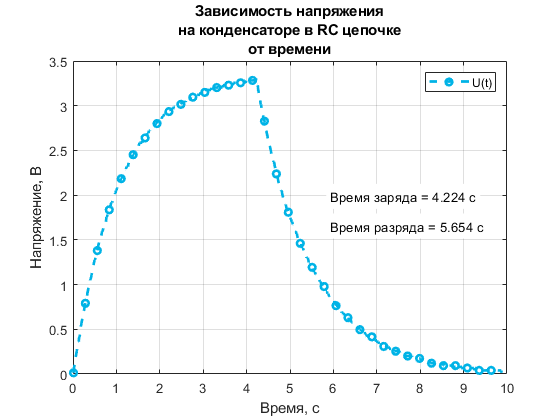

plot(t, U, 'g--o', 'MarkerIndices', 1:25:length(U), 'LineWidth', 2, 'MarkerSize', 5, 'Color', [0, 0.7, 0.9]);
grid on;
set(gcf, 'Visible', 'on');
title({'Зависимость напряжения', 'на конденсаторе в RC цепочке', 'от времени'});
xlabel("Время, с");
ylabel("Напряжение, В");
legend("U(t)", "Location", 'northeast');
text(max(t) * 0.6, max(U) * 0.6, ['Время заряда = ', num2str(tCharge), ' с'], 'BackgroundColor', 'w');
text(max(t) * 0.6, max(U) * 0.5, ['Время разряда = ', num2str(tDischarge), ' с'], 'BackgroundColor', 'w');

saveas(f, "capacitor.svg");